# Cost Correlations Homework

Peters, Timerhaus, and West Chapter 6

Kathryn Atherton

January 25, 2019

ABE 55800

## Problem 6-1

The purchased cost of a shell-and-tube heat exchanger (floating-head and carbon-steel tubes) with 100 m^2 of heating surface was $4200 in 1990. What will be the 1990 purchased cost of a similar heat exchanger with 20 m^2 of heating surface if the purchased cost capacity exponent is 0.60 for surface areas ranging from 10 to 40 m^2? If the purchased cost capacity exponent for this type of exchanger is 0.81 for surface areas ranging from 40 to 200 m^2, what will be the purchased cost of a heat exchanger with 100 m^2 of heating surface in 2000?

Equation 6-2: $\textrm{cost}\;\textrm{of}\;\textrm{equipment}\;a=\frac{\mathrm{index}\;\mathrm{year}\;2}{\mathrm{index}\;\mathrm{year}\;1}\left(\textrm{cost}\;\textrm{of}\;\textrm{equipment}\;b\right)X^{\mathrm{cost}\;\mathrm{capacity}\;\mathrm{exponent}}$

clear;
cost_100m2_1990         = 4200;                             % [$]
X_20m2                  = 20;                               % [m^2]
X_100m2                 = 100;                              % [m^2]
X                       = X_20m2 / X_100m2;                 % [-]
exp_10_40               = 0.60;                             % [-]
cost_20m2_1990          = cost_100m2_1990 * X ^ exp_10_40   % [$]

cost_20m2_1990 = 1.5991e+03

**Answer:** The 1990 cost of the 20 m^2 shell-and-tube heat exchanger is **$1599.10**.

index_1990              = 357.6;                            % [-], from Table 6-2 (page 238)
index_2000              = 394.1;                            % [-], from Table 6-2 (page 238)
exp_40_200              = 0.81;                             % [-]
cost_100m2_2000         = cost_100m2_1990 * (index_2000 / ...
                            index_1990)                     % [$]

cost_100m2_2000 = 4.6287e+03

**Answer: **The 2000 cost of the 100 m^2 shell-and-tube heat exchanger is **$4,628.70**.

## Problem 6-2

Plot the 2000 purchased cost of the shell-and-tube heat exchanger outlined in Problem 6-1 as a function of the surface area from 10 to 200 m^2. Note that the purchased cost capacity exponent is not constant over the range of surface area requested. 

Equation 6-2: $\textrm{cost}\;\textrm{of}\;\textrm{equipment}\;a=\frac{\mathrm{index}\;\mathrm{year}\;2}{\mathrm{index}\;\mathrm{year}\;1}\left(\textrm{cost}\;\textrm{of}\;\textrm{equipment}\;b\right)X^{\mathrm{cost}\;\mathrm{capacity}\;\mathrm{exponent}}$

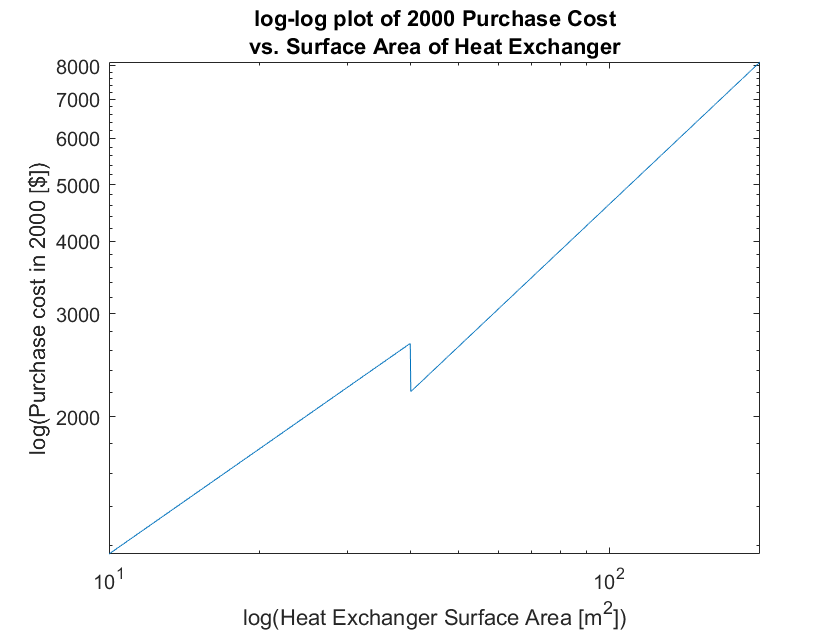

clear; 
cost_100m2_1990         = 4200;                              % [$]
X_plot                  = 10:0.1:200;                        % [m^2]
X_100m2                 = 100;                               % [m^2]
X                       = X_plot ./ X_100m2;                 % [-]
exp_10_40               = 0.60;                              % [-]
exp_40_200              = 0.81;                              % [-]
index_1990              = 357.6;                             % [-]
index_2000              = 394.1;                             % [-]
index                   = index_2000 / index_1990;           % [-]
for i = 1:1:length(X_plot)
    if X_plot(i) <= 40
        cost_2000(i)    = cost_100m2_1990 * index * (X(i) ...
                            ^ exp_10_40);                     % [$]
    else 
        cost_2000(i)    = cost_100m2_1990 * index * (X(i) ...
                            ^ exp_40_200);                    % [$]
    end
end

figure
loglog(X_plot, cost_2000)
title({"log-log plot of 2000 Purchase Cost","vs. Surface Area of Heat Exchanger"})
xlabel('log(Heat Exchanger Surface Area [m^2])')
ylabel('log(Purchase cost in 2000 [$])')

## Problem 6-7

The purchased cost equipment for a solid processing plant is $500,000. The plant is to be constructed as an addition to an existing plant. Estimate the total capital investment and the fixed-capital investment for the plant. What percentage and amount of the fixed-capital investment are due to cost for engineering and supervision, and what percentage and amount for the contractor’s fee. 

clear;
equipment               = 500000;                           % [$]
equipment_perc_fci      = mean([15,40])/100;                % [%], from Table 6-3 (page 240)
fci                     = equipment / equipment_perc_fci    % [$]

fci = 1.8182e+06

**Answer: **The fixed-capital iinvestment for the plant is **$1,818,200**.

wci                     = mean([10,20])/100;                % [%], from page 233
tci                     = fci / (1-wci)                     % [$], from page 232

tci = 2.1390e+06

**Answer: **The total capital investment for the plant is **$2,139,000**.

eng_perc_fci            = mean([4, 20])                     % [%], from Table 6-3 (page 240)

eng_perc_fci = 12

eng_fci                 = eng_perc_fci / 100 * fci          % [$]

eng_fci = 2.1818e+05

**Answer: **The engineering cost and supervision makes up **12%** of the fixed-capital investment, or **$218,180**.

contractor_perc_fci     = mean([2,6])                       % [%], from Table 6-3 (page 240)

contractor_perc_fci = 4

contractor_fci          = contractor_perc_fci / 100 * fci   % [$]

contractor_fci = 7.2727e+04

**Answer: **The contractor's fee makes up **4%** of the fixed-capital investment, or **$72,727**.

## Problem 6-10

The total capital investment for a chemical plant is $1,000,000, and the working capital is $100,000. If the plant can produce an average of 8,000 kg of final product per day during a 365-day year, what selling price in dollars per kilogram of product would be necessary to give a turnover ratio of 1.0?

clear;
tci                     = 1000000;                          % [$]
wci                     = 100000;                           % [$]
product                 = 8000;                             % [kg / day]
days                    = 365;                              % [days / year]
ratio                   = 1.0;                              % [-]
fci                     = tci - wci;                        % [$], from page 232

Equation 6-11: $\mathrm{turnover}\;\mathrm{ratio}=\frac{\mathrm{gross}\;\mathrm{annual}\;\mathrm{sales}}{\mathrm{fixed}-\mathrm{capital}\;\mathrm{investment}}$

gross_sales             = ratio * fci;                      % [$]
product_year            = product * days;                   % [kg / year]

Equation 6-12: $\mathrm{annual}\;\mathrm{sales}\;\mathrm{revenue}=\sum \left(\mathrm{sales}\;\mathrm{of}\;\mathrm{product}\right)\left(\mathrm{product}\;\mathrm{sales}\;\mathrm{price}\right)$

price_kg                = gross_sales / product_year        % [$ / kg]

price_kg = 0.3082

**Answer: **The selling price of the product to give a turnover ratio of 1.0 should be **$0.31/kg**.

## Problem 6-11

A process plant was constructed in the Philadelphia area (Mid-Atlantic) at a labor cost of $425,000 in 1990. What would be the labor cost for the same plant located in the Miami, Florida area (south Atlantic) if it were constructed in late 1998? Assume, for simplicity, that the relative labor rate and relative productivity factor have remained constant. 

clear;
labor_phil_cost_1990    = 425000;                           % [$]
index_1990              = 357.6;                            % [-], from Table 6-2 (page 238)
index_1998              = 389.5;                            % [-], from Table 6-2 (page 238)
labor_phil_index_1998   = 1.06;                             % [-], from Table 6-12 (page 256)
labor_miami_index_1998  = 0.84;                             % [-], from Table 6-12 (page 256), 
prod_phil_index_1998    = 0.96;                             % [-], from Table 6-12 (page 256)
prod_miami_index_1998   = 0.91;                             % [-], from Table 6-12 (page 256
labor_phil_cost_1998    = labor_phil_cost_1990 * ...
                            (index_1998 / index_1990);      % [$]
rel_lab_rate            = labor_miami_index_1998 / ...
                            labor_phil_index_1998;          % [-]
rel_prod_rate           = prod_miami_index_1998 ...
                            / prod_phil_index_1998;         % [-]
rel_lab_cost            = rel_lab_rate / rel_prod_rate;     % [-]
labor_miami_cost_1998   = labor_phil_cost_1998 * ...
                            rel_lab_cost                    % [$]

labor_miami_cost_1998 = 3.8699e+05

**Answer: **The labor cost for the same plant in Miami (south Atlantic) constructed in late 1998 would be **$386,990**.

## Problem 6-13:

The total capital investment for a conventional chemical plant is $1,500,000, and the plant produces 3 million kg of product annually. The selling price of the product is $0.82/kg. Working capital amounts to 15 percent of the total capital investment. The investment is from company funds, and no interest is charged. Delivered raw materials costs for the product are $0.09/kg; labor, $0.08/kg; utilities, $0.05/kg; and packaging, $0.008/kg. Distribution costs are 5 percent of the total product cost. Estimate the following

- Manufacturing cost per kilogram of product

- Total product cost per year

- Profit per kilogram of product before taxes

- Profit per kilogram of product after income taxes at 35 percent of gross profit

clear; 
tci                     = 1500000;                          % [$]
product                 = 3000000;                          % [kg / year]
price                   = 0.82;                             % [$ / kg]
wci                     = 0.15 * tci;                       % [$]
raw_materials           = 0.09;                             % [$ / kg]
labor                   = 0.08;                             % [$ / kg]
utilities               = 0.05;                             % [$ / kg]
packaging               = 0.008;                            % [$ / kg]
dist                    = 0.05;                             % [% of tpc]
tax                     = 0.35;                             % [% of gross profit]
fci                     = tci - wci;                        % [$]
maintenance             = 0.1 * fci;                        % [$]
maintenance_kg          = maintenance / product;            % [$ / kg]
var_cost                = raw_materials + maintenance_kg ...
                            + utilities + packaging;        % [$ /kg]
supervision             = 0.2 * labor;                      % [$ / kg]
insurance               = 0.01 * fci / product;             % [$ / kg]
depreciation            = 0.15 * fci / product;             % [$ / kg]
plant_overhead          = 0.6;                              % [% of fixed costs]
fix_cost                = (labor + supervision + insurance ...
                            + depreciation) / (1 - ...
                            plant_overhead);                % [$ / kg]
manufacturing           = var_cost + fix_cost               % [$ / kg]

manufacturing = 0.6005

**Answer:** The manufacturing cost is **$0.60 / kg**.

tpc                     = manufacturing / (1- dist)         % [$ / kg]

tpc = 0.6321

**Answer: **The total product cost is **$0.63 / kg**.

tpc_year                = tpc * product                     % [$ / year]

tpc_year = 1.8963e+06

**Answer: **The total product cost per year is **$1,896,300**.

profit                  = price - tpc                       % [$ / kg]

profit = 0.1879

**Answer: **The profit before taxes is **$0.19 / kg**.

profit_taxed            = profit * (1 - tax)                % [$ / kg]

profit_taxed = 0.1221

**Answer: **The profit after taxes is **$0.12 / kg**.

## Problem 6-14

Estimate the manufacturing cost per 100 kg of product under the following conditions:

- Fixed-capital investment = $4,000,000

- Annual production output = 9 million kg of product

- Raw materials cost = $0.25/kg of product

- Utilities

-         800-kPa steam = 50 kg/kg of product

-         Purchased electric power = 0.9 kWh/kg of product

-         Filtered and softened water = 0.083 m3/kg of product

- Operating labor = 12 persons per shift at $25.00 per employee-hour.

- Plant operates three hundred 24-h days per year

- Corrosive liquids are involved

- Shipments are in bulk carload lots

- A large amount of direct supervision is required

- There are no patent, royalty, interest, or rent charges

- Plant overhead costs amount to 50 percent of the cost for operating labor, supervision, and maintenance

clear;
product                 = 100;                              % [kg]
fci                     = 4000000;                          % [$]
output                  = 9000000;                          % [kg]
raw_materials           = 0.25;                             % [$ / kg]
utilities               = (50 * 4.4 / 1000) + (0.9 * 0.045)...
                            + (0.083 * 0.53 / 1000 * 997);  % [$ / kg]
labor                   = 12 * 25 * 24 * 300 / output;      % [$ / kg]
supervision             = 0.2 * labor;                      % [$ / kg]
maintenance             = mean([7,11]) / 100 * fci / ...
                            output;                         % [$ / kg]
distribution            = 0.02;                             % [% of tpc]
plant_overhead          = 0.5 * (labor + maintenance + ...
                            supervision);                   % [$ / kg]
var_cost                = raw_materials + maintenance + ...
                            utilities;                      % [$ / kg]
fix_cost                = plant_overhead + labor + ...
                            supervision;                    % [$ / kg]
manufacturing           = var_cost + fix_cost;              % [$ / kg]
manufacturing_100       = manufacturing * product           % [$ / 100 kg]

manufacturing_100 = 104.6358

**Answer: **The manufacturing cost is **$104.64 / 100 kg**.

### Problem 6-16: 

A process plant making 5000 kg/day of a product selling for $1.75/kg has annual variable production costs of $2,000,000 at 100 percent capacity and fixed costs of $700,000. What is the fixed cost per kilogram at the breakeven point? If the selling price of the product is increased by 10 percent, what is the dollar increase in net profit at full capacity if the income tax rate is 35 percent of gross earnings?

clear;
product                 = 5000;                             % [kg / day]
price                   = 1.75;                             % [$ / kg]
var_cost                = 2000000;                          % [$ / year at 100% capacity]
fix_cost                = 700000;                           % [$ / year at 100% capacity]
tax                     = 0.35;                             % [% of earnings]
income                  = product * price * 365;            % [$ / year]
slope                   = income / product;                 % [$ / kg]
product_be              = slope * (product);                % [$]
fix_cost_kg             = fix_cost / product_be             % [$ / kg]

fix_cost_kg = 0.2192

**Answer: **The fixed cost is **$0.22 / kg**.

price                   = price * 1.1;                      % [$ / kg]
income_new              = product * price * 365;            % [$ / year]
earnings                = income - var_cost - fix_cost;     % [$ / year]
earnings_new            = income_new - var_cost - fix_cost; % [$ / year]
profit                  = earnings * (1 - tax);             % [$ / year]
profit_new              = earnings_new * (1 - tax);         % [$ / year]
increase                = profit_new - profit               % [$ / year]

increase = 2.0759e+05

**Answer: **The increase in profits with the increase in price is **$207,590 / year**.

## Problem 6-17: 

A rough rule of thumb for the chemical industry is that $1 of annual sales requires $2 of fixed-capital investment. In a chemical processing plant where this rule applies, the total capital investment is $2,500,000 and the working capital is 20 percent of the total capital investment. The annual total product cost amounts to $1,500,000. If the income tax rates on gross earnings total is 35 percent, determine the following: 

- Percent of total capital investment returned annually as gross earnings

- Percent of total capital investment returned annually as net profit

clear;
sales                   = 0.5;                              % [% of fci]
tci                     = 2500000;                          % [$]
wci                     = 0.2 * tci;                        % [$]
tax                     = 0.35;                             % [$]
fci                     = tci - wci;                        % [$]
tpc                     = 1500000;                          % [$]
sales                   = sales * fci;                      % [$]
profit                  = sales * (1 - tax);                % [$]
perc_tci_earnings       = sales / tci * 100                 % [% of tci]

perc_tci_earnings = 40

**Answer: 40%** percent of total capital investment is returned annually as gross earnings. 

perc_tci_profit         = profit / tci * 100                % [% of tci]

perc_tci_profit = 26

**Answer: 26%** percent of total capital investment is returned annually as net profit. 